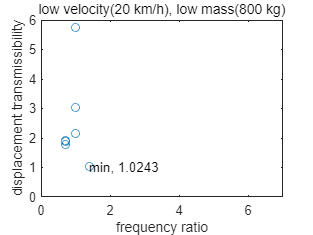

% © 2022 2018100778 최동욱 기계공학과 <ch3044637@khu.ac.kr>
% 2022-1학기 기계진동 term_project
% 다양한 조합에 대한 변위 전달률

clear; clc;

% m = 800
m = 800;

% initial condition
k = [2e4 4e4 8e4];
c = [1e3 2e3 3e3];
v = [20 100];
l = 0.005; hour2sec = 3600;

% natural frequency, driving frequency, frequency ratio, damping ratio
Wn = sqrt(k/m);
Wb = v*2*pi/(l*hour2sec);
r = [Wb(1)/Wn(1) Wb(1)/Wn(1) Wb(1)/Wn(1)...
    Wb(1)/Wn(2) Wb(1)/Wn(2) Wb(1)/Wn(2)...
    Wb(1)/Wn(3) Wb(1)/Wn(3) Wb(1)/Wn(3);...
    Wb(2)/Wn(1) Wb(2)/Wn(1) Wb(2)/Wn(1)...
    Wb(2)/Wn(2) Wb(2)/Wn(2) Wb(2)/Wn(2)...
    Wb(2)/Wn(3) Wb(2)/Wn(3) Wb(2)/Wn(3)];
zeta = [c/(2*sqrt(m*k(1))) c/(2*sqrt(m*k(2))) c/(2*sqrt(m*k(3)));...
    c/(2*sqrt(m*k(1))) c/(2*sqrt(m*k(2))) c/(2*sqrt(m*k(3)))];

% displacement transmissibility
for n = 1:2
    for i = 1:9
        XperY(n, i) = sqrt((1+(2*zeta(n,i)*r(n,i))^2)/((1-r(n,i)^2)^2+(2*zeta(n,i)*r(n,i))^2));
    end
end

% plot
plot(r(1,:),XperY(1,:),'o');
axis([0, 7, 0, 6]);
title('low velocity(20 km/h), low mass(800 kg)');
xlabel('frequency ratio');
ylabel('displacement transmissibility');
text(r(1,1),XperY(1,3),'min, 1.0243');

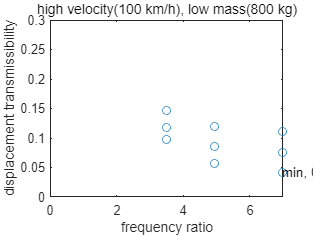


plot(r(2,:),XperY(2,:),'o');
axis([0, 7, 0, 0.3]);
title('high velocity(100 km/h), low mass(800 kg)');
xlabel('frequency ratio');
ylabel('displacement transmissibility');
text(r(2,1),XperY(2,1),'min, 0.0421');

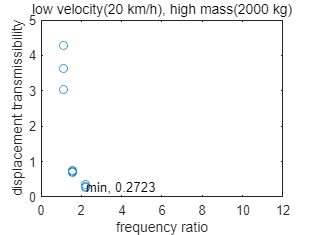


% m = 2000
m = 2000;

% natural frequency, driving frequency, frequency ratio, damping ratio
Wn = sqrt(k/m);
Wb = v*2*pi/(l*hour2sec);
r = [Wb(1)/Wn(1) Wb(1)/Wn(1) Wb(1)/Wn(1)...
    Wb(1)/Wn(2) Wb(1)/Wn(2) Wb(1)/Wn(2)...
    Wb(1)/Wn(3) Wb(1)/Wn(3) Wb(1)/Wn(3);...
    Wb(2)/Wn(1) Wb(2)/Wn(1) Wb(2)/Wn(1)...
    Wb(2)/Wn(2) Wb(2)/Wn(2) Wb(2)/Wn(2)...
    Wb(2)/Wn(3) Wb(2)/Wn(3) Wb(2)/Wn(3)];
zeta = [c/(2*sqrt(m*k(1))) c/(2*sqrt(m*k(2))) c/(2*sqrt(m*k(3)));...
    c/(2*sqrt(m*k(1))) c/(2*sqrt(m*k(2))) c/(2*sqrt(m*k(3)))];

% displacement transmissibility
for n = 1:2
    for i = 1:9
        XperY(n, i) = sqrt((1+(2*zeta(n,i)*r(n,i))^2)/((1-r(n,i)^2)^2+(2*zeta(n,i)*r(n,i))^2));
    end
end

% plot
plot(r(1,:),XperY(1,:),'o');
axis([0, 12, 0, 5]);
title('low velocity(20 km/h), high mass(2000 kg)');
xlabel('frequency ratio');
ylabel('displacement transmissibility');
text(r(1,1),XperY(1,1),'min, 0.2723');

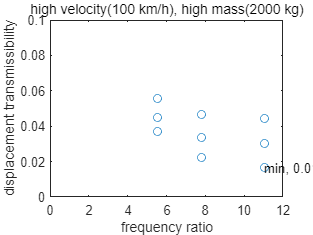


plot(r(2,:),XperY(2,:),'o');
axis([0, 12, 0, 0.1]);
title('high velocity(100 km/h), high mass(2000 kg)');
xlabel('frequency ratio');
ylabel('displacement transmissibility'); 
text(r(2,1),XperY(2,1),'min, 0.0166');